clear variables;
addPath;

%tempo reduction param
para.kF = 20;
para.redL = 5;

%ACA param
para.nMi = 5;
para.nMa = 10;
para.ini='r';
para.k=8;
para.nIni=1;
para.reduct = true;

%HACA param
para2 = para;
para2.nMi = 4;
para2.nMa = 8;
para2.k=4;
para2.nIni=10;
paraH = [para para2];

## Select data (mice)

all_paths = getAllFile('../feat/20210811/');

% multiple
%
% micenames = {'B' , 'DW', 'LKB', 'LW', 'RK', 'SW', 'LKW' , 'MW', 'WT'};
% micenames = {'LKW' , 'MW'};
% for i=1:size(micenames,2)
%     sel = find(contains(all_paths, ['-',micenames{i},'-']));
%     paths={all_paths{sel}};
%     [X, ends, names] = loadData(paths, para);
%     ACA_mice(paths,para,folder,micenames{i});
% end

% single
micename = 'B';
sel = find(contains(all_paths, ['-',micename,'-']));
paths=all_paths(sel);
[X, ends, names] = loadData(paths,para);

 9347 -> 2598
 8247 -> 2080


K = conKnl(conDist(X, X));
seg = segIniR(K, para);
segResult = segAca(K, para, seg);

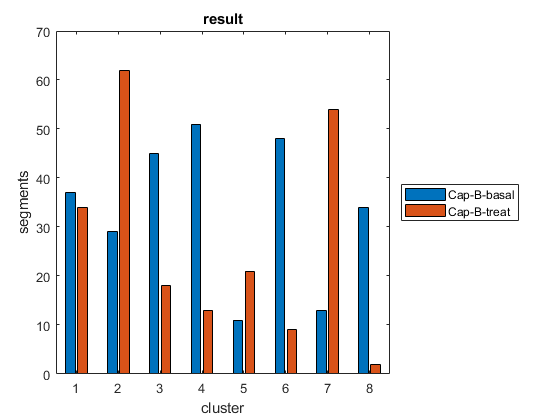

[sP, LP, segs, labels] = segPart(segResult.s,segResult.G,ends);
clusterPlot(labels,names,'./test.png');

## Cluster Selection

sel_num = 2;
sel = largeDiff(labels,sel_num,'scale2');
[nX,ns,splits] = selectCluster(X,segResult.s,segResult.G,sel,ends);
% [nX,ns,splits] = concateSel(nX,ns,splits,nX,ns,splits);

nseg = reCluster(nX,ns,sel_num);